# Shannon - Nyquist Sampling and Aliasing Example

% -------------------------------------------------------------------------
%
% -- Aim --
% Illustration of Shannon - Nyquist sampling theorem and aliasing if the sampling rate is not high enough
%
% -- Notes --
% This is a Matlab live script to be run interactively in Matlab.
% Requires Matlab 2018a or above. No additional toolboxes are required.
%
% -- Version --
% 2020.08.20 - v1 - initial script
% 2025.05.18 - v1.1 - modified script (no Fourier transform, no spectra,
%                     only signals in time domain)
%
% -- Credits --
% 
% v1: Alex Casson, available at 
% https://uk.mathworks.com/matlabcentral/fileexchange/79331-nyquist-sampling-and-aliasing-example?s_tid=srchtitle&status=SUCCESS
%
% v1.1: G. Fenu
%       course --> 034IN - Fundamentals of Automatic Control 
% -------------------------------------------------------------------------

% Initialise Matlab
clear
close all


## Settings

Change these settings to investigate the signals produced when sampling a simple sine wave. 

### Aliasing and Sampling Frequency

If the original continuous-time  signal's highest frequency exceeds half the sampling rate, **aliasing** will occur; i.e., the signal reconstructed using the samples appears as a distorted and corrupted version of the original signal: 

- high-frequency components in the original continuous-time signal can be misinterpreted as components at lower frequencies;

- in the reconstructed signal, components may appear at frequencies that were not present in the original signal. 

fs =100; % sampling frequency [Hz]
f = 6;  % signal frequency   [Hz]
duration =1; % duration to plot [s]

% Hint for Hands-On Experiments:
% select
% 1) fs = 10, f = 38 and duration = 3   --> compare both the slow sampled signal and the reconstructed one
%                                           with the original fast continuous-time signal
% 2) fs = 100, f = 9 and duration = 1  --> compare both the sampled signal and the reconstructed one with the
%                                          original continuous-time signal. 
%                                          Note the delay when comparing the original and the reconstructed signal:
%                                          the latter lags behind the former.

## Signal to sample

The signal to sample is just a sine wave at the assigned frequency. Direct sampling records the amplitude of the input waveform at a fixed periodic rate. Only these sample points are seen in the discrete time domain.

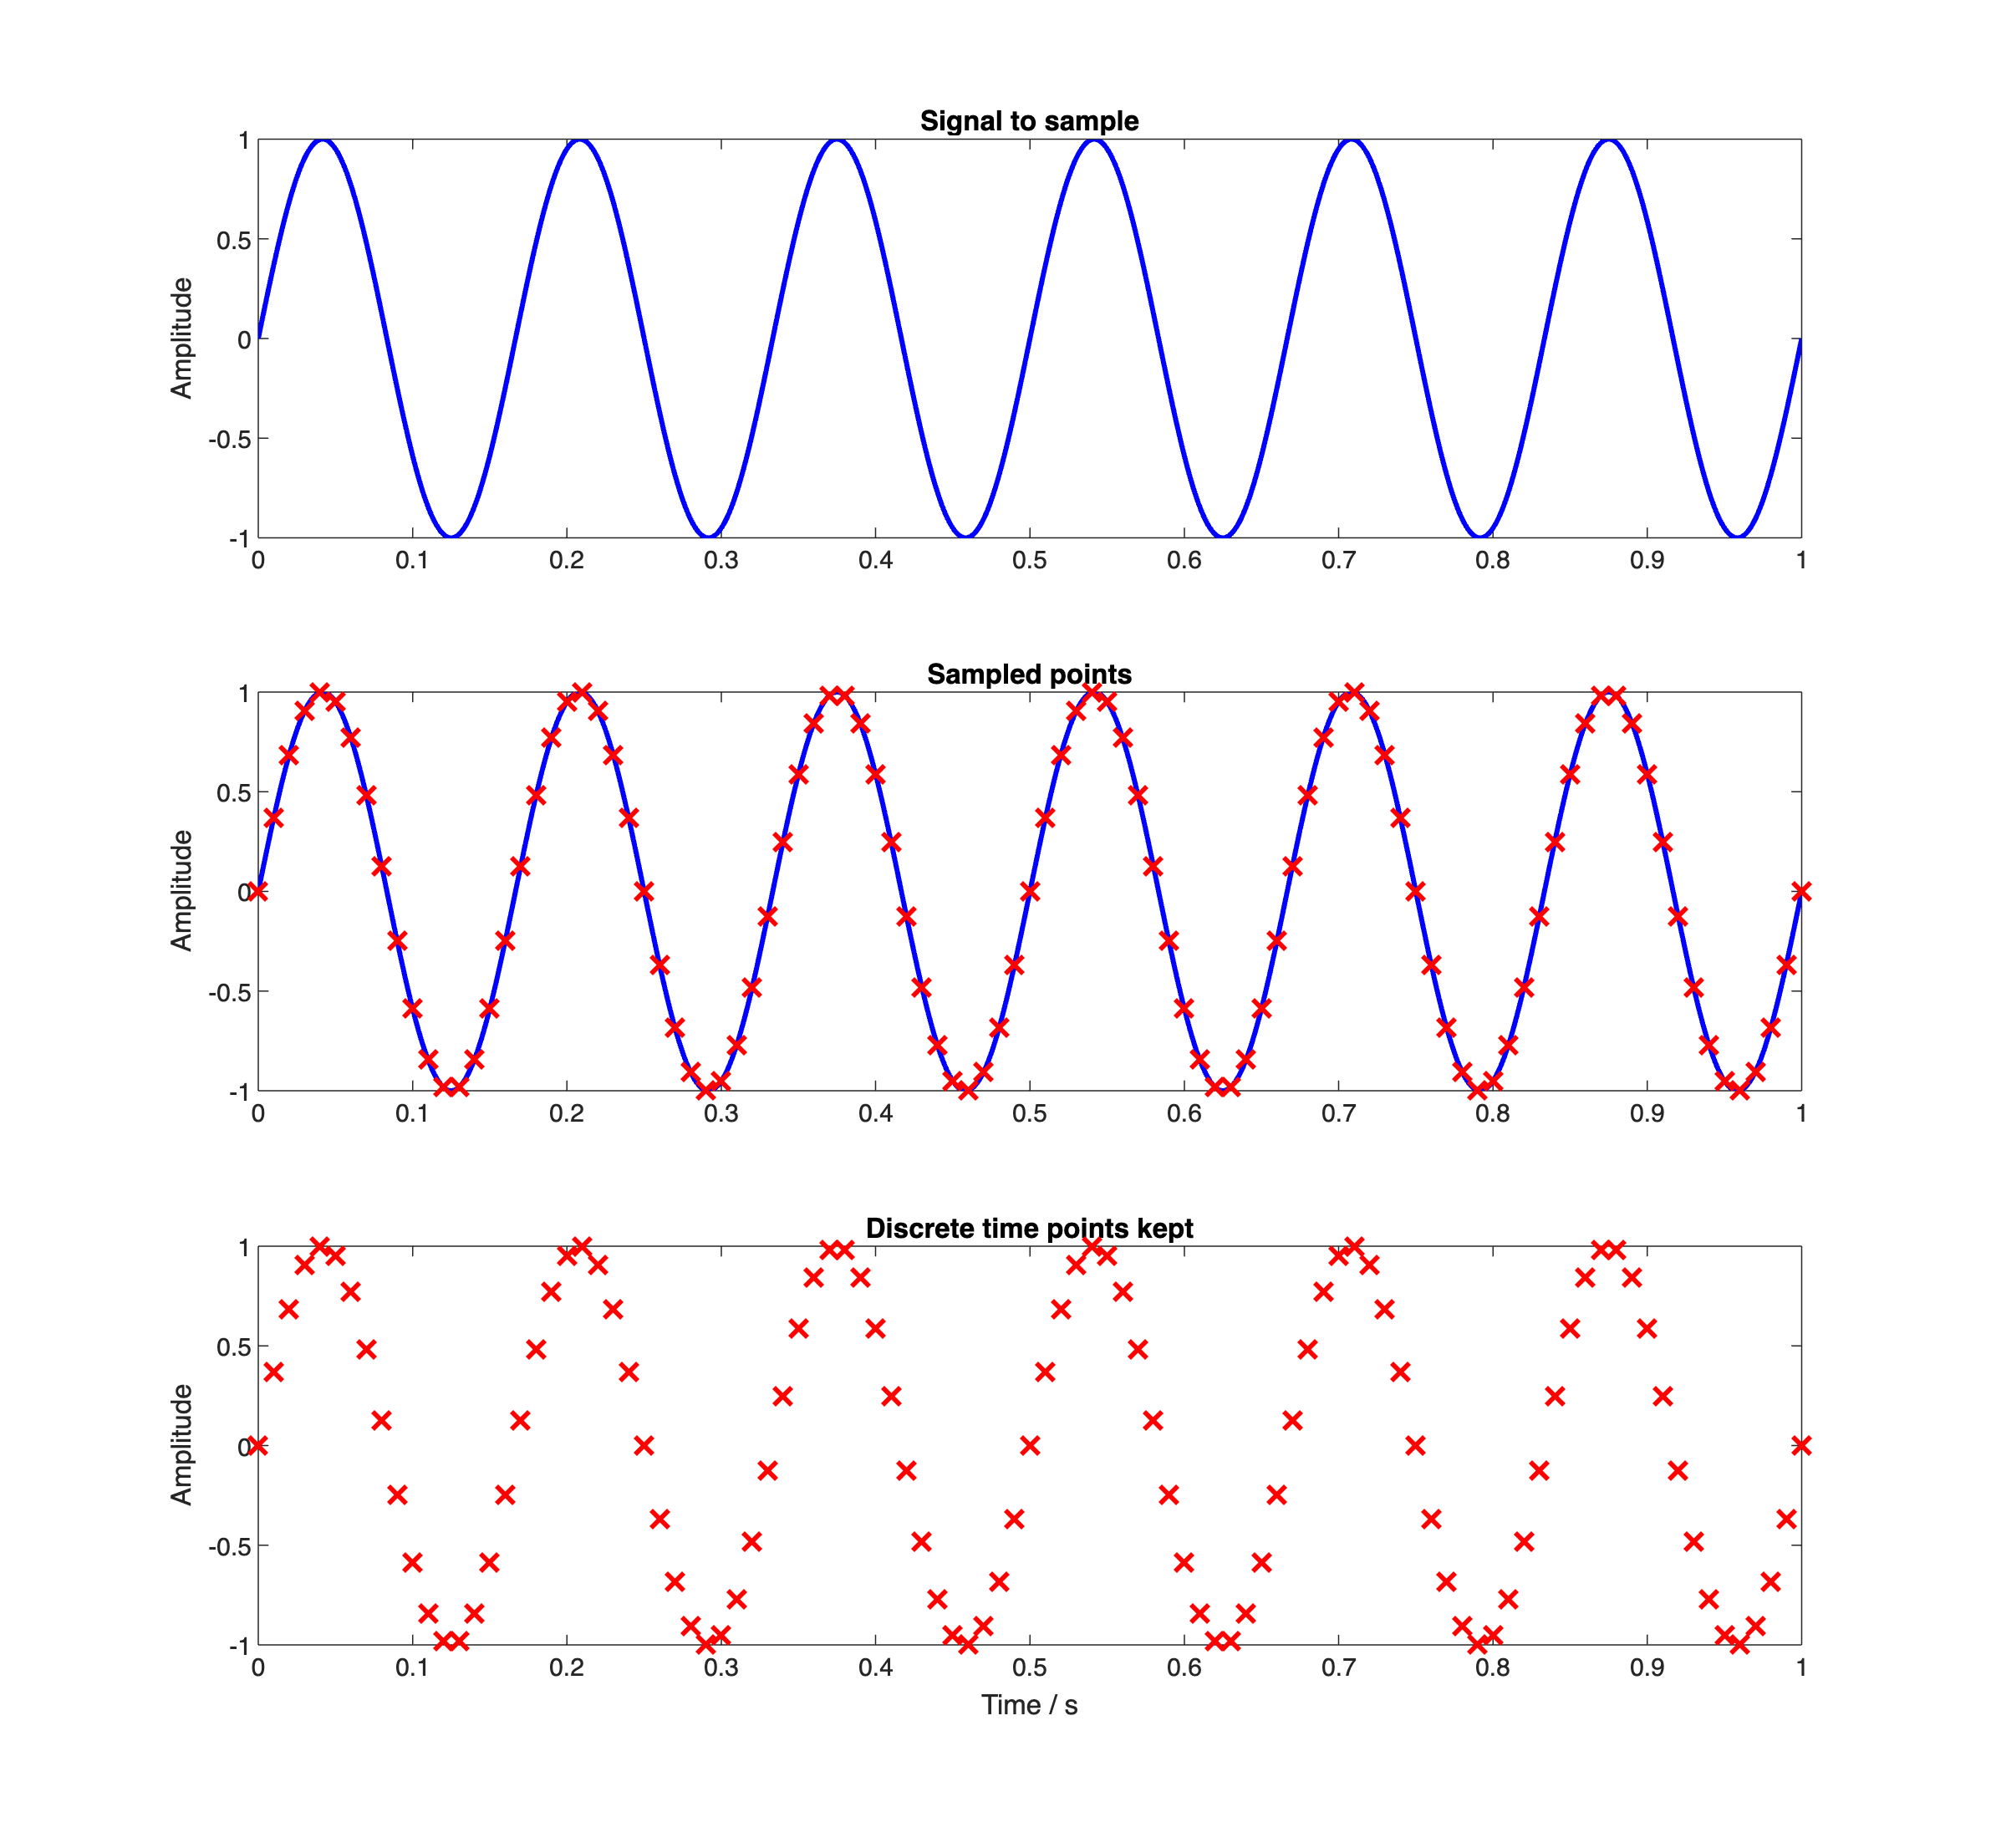

t = 0:1/fs:duration;
sig = sin(2*pi*f*t);
fs_full = 1000;
t_full = 0:1/fs_full:duration;
sig_full = sin(2*pi*f*t_full);
figure('Units', 'centimeters','Position',[0.5, 0.5, 28, 26])
subplot(311); plot(t_full,sig_full,'b-','LineWidth',2); ylabel('Amplitude'); 
              title('Signal to sample'); xlim([0, duration])
subplot(312); plot(t_full,sig_full,'b-',t,sig,'rx','LineWidth',2,'MarkerSize',10); ylabel('Amplitude');
              title('Sampled points'); xlim([0, duration])
subplot(313); plot(t,sig,'rx','LineWidth',2,'MarkerSize',10); ylabel('Amplitude'); 
              title('Discrete time points kept'); xlim([0, duration]); xlabel('Time / s')

## Reconstructed Signal using a Zero Order Hold

When converting back to the analogue domain the most common approach is to use a Zero Order Hold - the signal is simply kept constant between the sample points. 

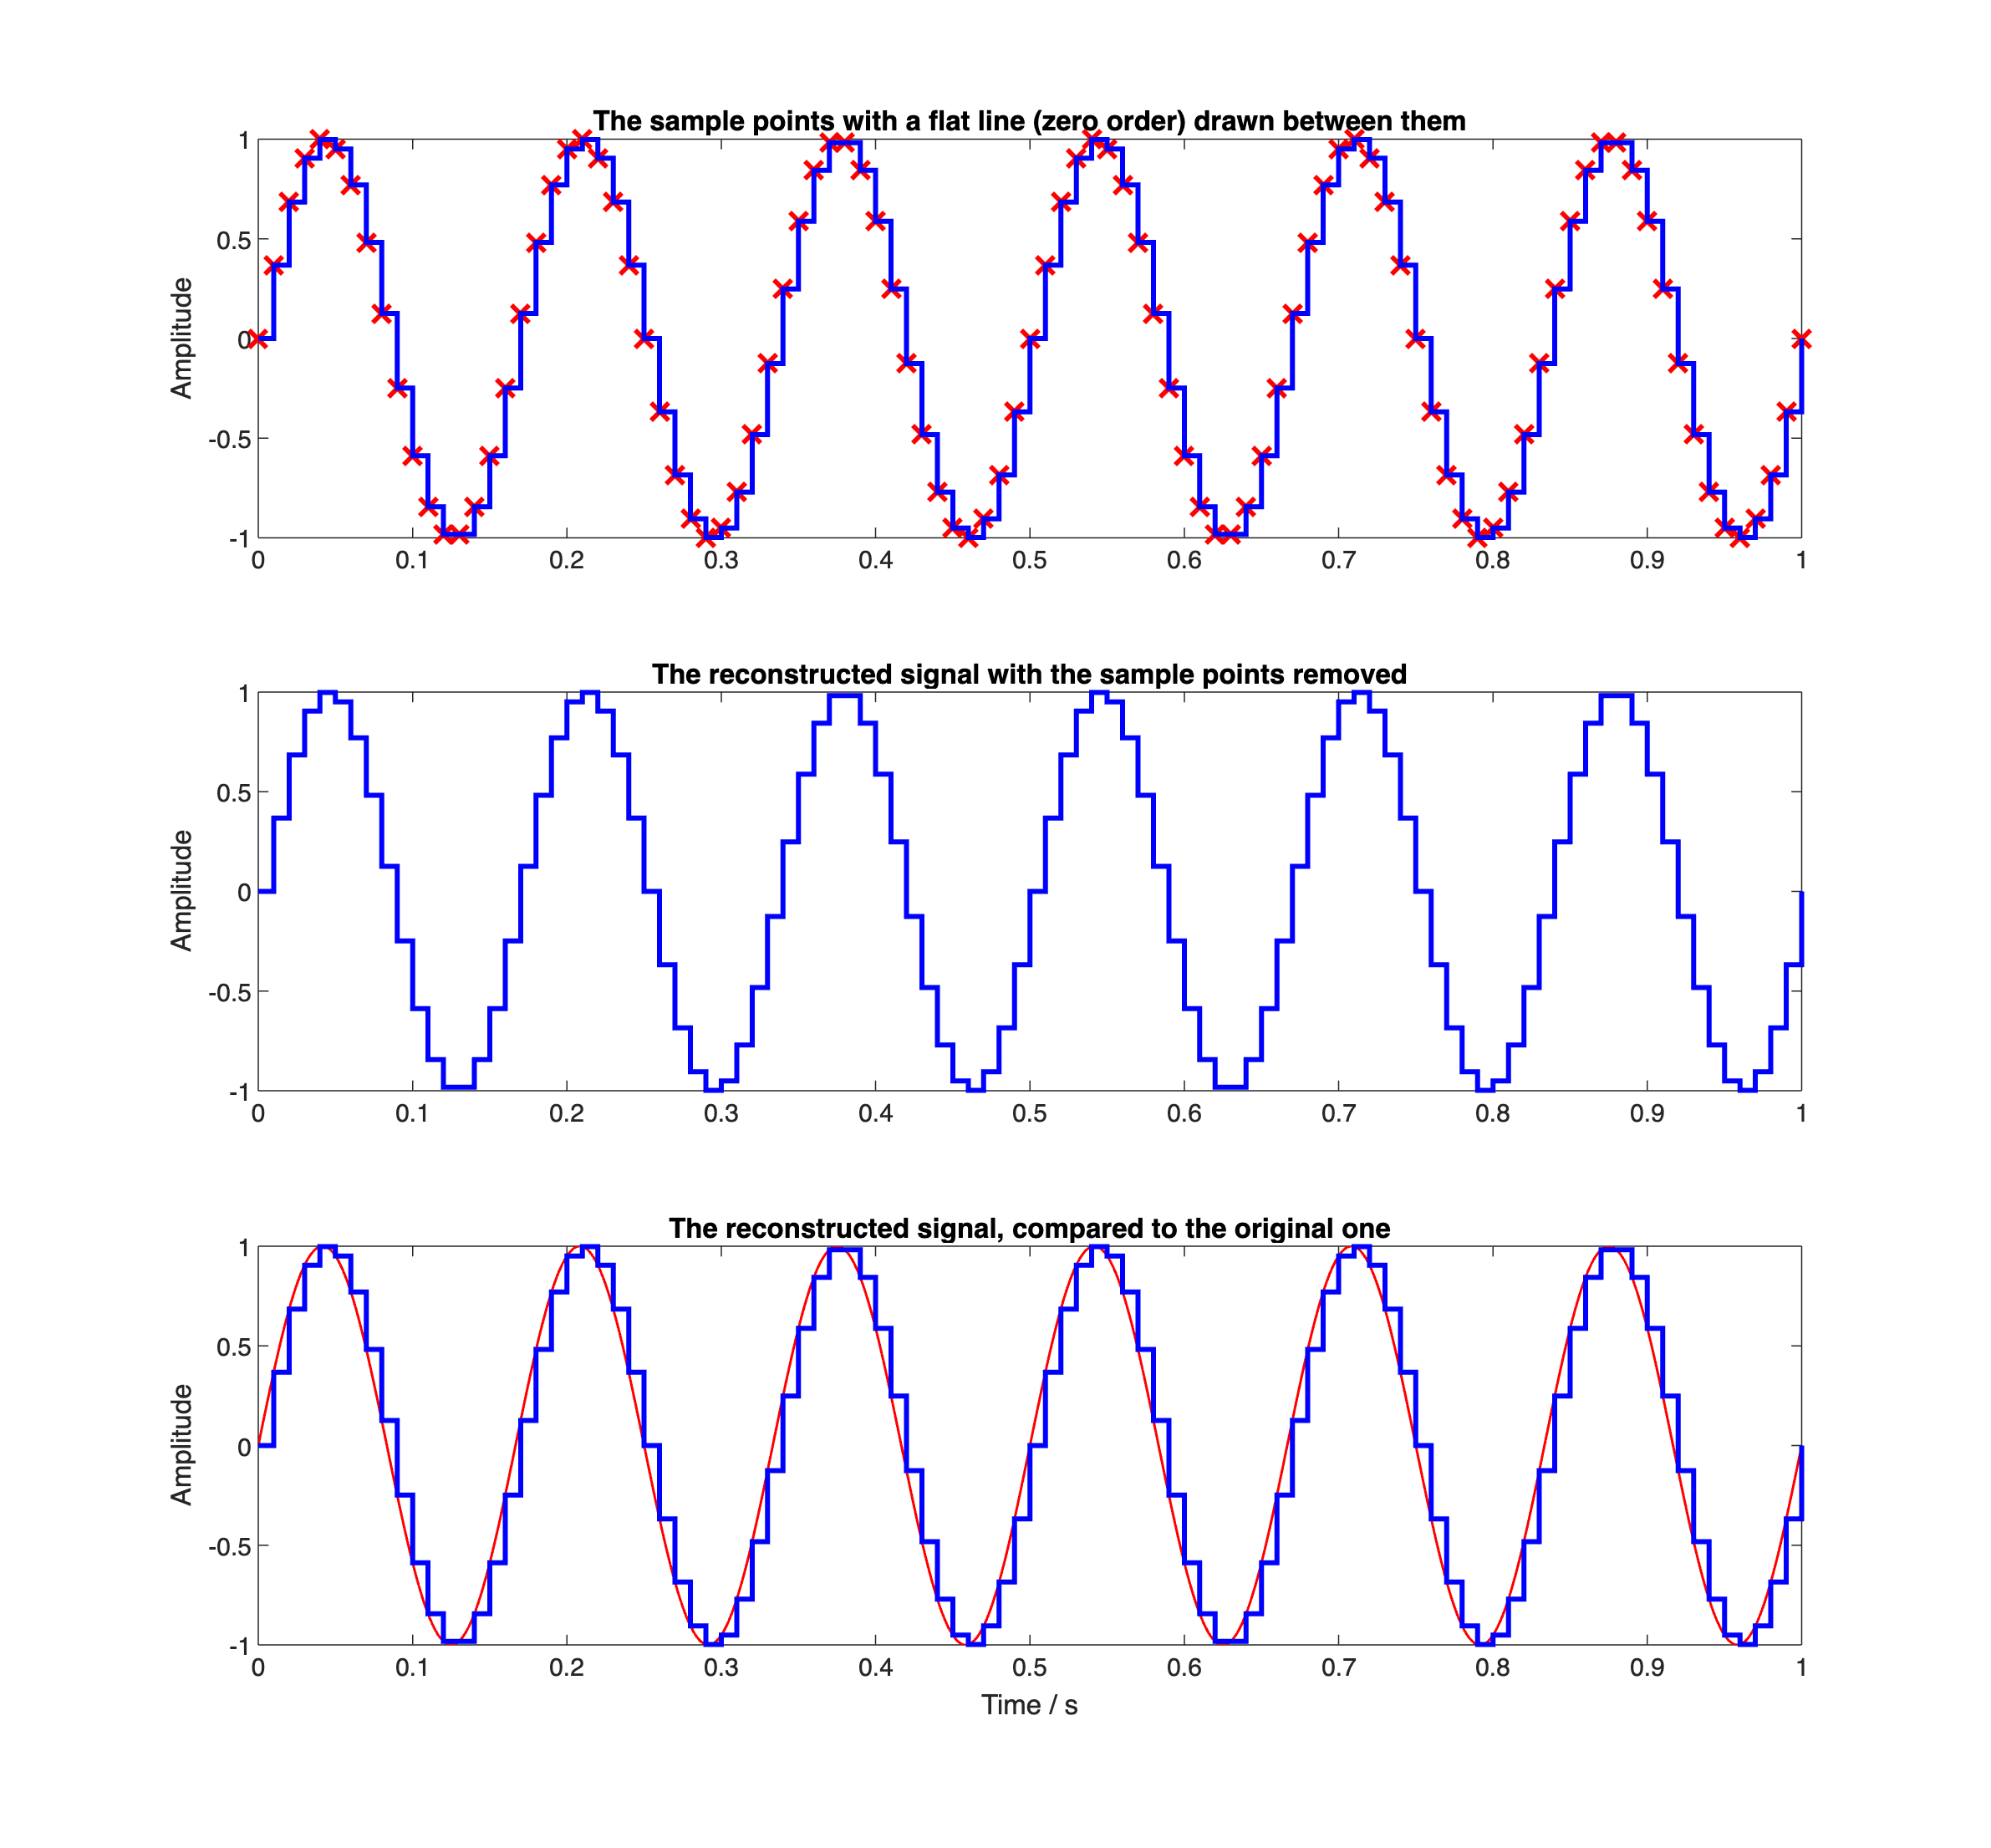

figure('Units', 'centimeters','Position',[0.5, 0.5, 28, 26])
subplot(311); plot(t,sig,'rx','LineWidth',2,'MarkerSize',10); 
              title('The sample points with a flat line (zero order) drawn between them'); 
              hold on
              stairs(t,sig,'b','LineWidth',2); ylabel('Amplitude'); xlim([0, duration]);
subplot(312); stairs(t,sig,'b','LineWidth',2); ylabel('Amplitude'); 
              title('The reconstructed signal with the sample points removed'); xlim([0, duration]);
subplot(313); plot(t_full,sig_full,'r-','LineWidth',1.0); 
              hold on; stairs(t,sig,'b','LineWidth',2); 
              ylabel('Amplitude'); xlabel('Time / s'); xlim([0, duration]);
              title('The reconstructed signal, compared to the original one')